% Lezione 4
% A teoria: matrici varie
% Facciamo una matrice casuale
A = rand(5)

A =     0.2312    0.3317    0.0943    0.7360    0.0548
    0.4035    0.1522    0.9300    0.7947    0.3037
    0.1220    0.3480    0.3990    0.5449    0.0462
    0.2684    0.1217    0.0474    0.6862    0.1955
    0.2578    0.8842    0.3424    0.8936    0.7202


% Questa è una matrice senza nessuna struttura particolare
% Come le diamo una struttura vera e propria?
% Ci sono due possibili comandi per le matrici triangolari
U = triu(A) % Triangle upper

U =     0.2312    0.3317    0.0943    0.7360    0.0548
         0    0.1522    0.9300    0.7947    0.3037
         0         0    0.3990    0.5449    0.0462
         0         0         0    0.6862    0.1955
         0         0         0         0    0.7202


L = tril(A) % Triangle lower

L =     0.2312         0         0         0         0
    0.4035    0.1522         0         0         0
    0.1220    0.3480    0.3990         0         0
    0.2684    0.1217    0.0474    0.6862         0
    0.2578    0.8842    0.3424    0.8936    0.7202


% Come facciamo una matrice triangolare con diagonale tutta a 0?
% Un modo: estraggo la diagonale e la sottraggo
D = diag(A)

D =     0.2312
    0.1522
    0.3990
    0.6862
    0.7202


% Non dà una matrice con solo la diagonale, ma un vettore
% Che si fa? POLIMORFISMO. È overloaded
% matrice->vettore diagonale, oppure vettore diagonale->matrice
% Quindi:
D = diag(diag(A))

D =     0.2312         0         0         0         0
         0    0.1522         0         0         0
         0         0    0.3990         0         0
         0         0         0    0.6862         0
         0         0         0         0    0.7202


U = U - D

U =          0    0.3317    0.0943    0.7360    0.0548
         0         0    0.9300    0.7947    0.3037
         0         0         0    0.5449    0.0462
         0         0         0         0    0.1955
         0         0         0         0         0


L = L - D

L =          0         0         0         0         0
    0.4035         0         0         0         0
    0.1220    0.3480         0         0         0
    0.2684    0.1217    0.0474         0         0
    0.2578    0.8842    0.3424    0.8936         0


% C'è un altro modo
help tril

 tril - Lower triangular part of matrix
    This MATLAB function returns the lower triangular portion of matrix A.

    Syntax
      L = tril(A)
      L = tril(A,k)

    Input Arguments
      A - Input matrix
        matrix
      k - Diagonals to include
        0 (default) | scalar

    Examples
      Extract Lower Triangular Portions of Matrix

    See also diag, triu, istril, bandwidth

    Introduced in MATLAB before R2006a
    Documentati

% Prende un secondo parametro k
% Quanti elementi prende sotto la diagonale
tril(A, 1) % Una diagonale in più

ans =     0.2312    0.3317         0         0         0
    0.4035    0.1522    0.9300         0         0
    0.1220    0.3480    0.3990    0.5449         0
    0.2684    0.1217    0.0474    0.6862    0.1955
    0.2578    0.8842    0.3424    0.8936    0.7202


tril(A, -1) % Una diagonale in meno

ans =          0         0         0         0         0
    0.4035         0         0         0         0
    0.1220    0.3480         0         0         0
    0.2684    0.1217    0.0474         0         0
    0.2578    0.8842    0.3424    0.8936         0


% Infatti:
isequal(L, tril(A, -1)) % Dà true

ans = logical
   1



% Creiamo una matrice simmetrica
S = A * A'

S =     0.7170    0.8330    0.5848    0.6226    1.0823
    0.8330    1.7747    0.9204    0.7756    1.4859
    0.5848    0.9204    0.5943    0.4770    0.9960
    0.6226    0.7756    0.4770    0.5982    0.9470
    1.0823    1.4859    0.9960    0.9470    2.2826


% Questo funziona sempre
% Sarà utile per creare dei test per risolvere sistemi
isequal(S, S') % Dà true

ans = logical
   1


% Spesso quando si lavora con le matrici sono molto grandi
% Anche 50000x50000
% Viene male controllarlo a mano
issymmetric(S) % Dà true

ans = logical
   1


issymmetric(A) % Dà false

ans = logical
   0



% Ci sono altri comandi che fanno controlli
istriu(U) % true

ans = logical
   1


istriu(L) % false

ans = logical
   0


istril(U) % false

ans = logical
   0


istril(L) % true

ans = logical
   1


istriu(D) % true

ans = logical
   1


istril(D) % true

ans = logical
   1


% Una matrice diagonale è un caso particolare di matrice triangolare superiore e inferiore
isdiag(U) % false

ans = logical
   0


isdiag(L) % false

ans = logical
   0


isdiag(D) % true

ans = logical
   1



% Ricostruiamo A dalle sue componenti
Anew = U + L + D

Anew =     0.2312    0.3317    0.0943    0.7360    0.0548
    0.4035    0.1522    0.9300    0.7947    0.3037
    0.1220    0.3480    0.3990    0.5449    0.0462
    0.2684    0.1217    0.0474    0.6862    0.1955
    0.2578    0.8842    0.3424    0.8936    0.7202


isequal(A, Anew) % true

ans = logical
   1



% Ultima: matrici ermitiane
ishermitian(A) % false

ans = logical
   0


% issymmetric() non funziona con numeri complessi, si usa questa
% Non la useremo mai per questo corso ma esiste

% L'ultima matrice con struttura particolare sono quelle ortogonali
% La trasposta è uguale all'inversa
% Generiamo una matrice ortogonale a partire da un'altra matrice
O = orth(A)

O =    -0.3444    0.1556    0.6030   -0.3252   -0.6228
   -0.5311   -0.7758   -0.1872    0.2107   -0.1914
   -0.3257   -0.1274    0.0331   -0.7438    0.5687
   -0.3069    0.0842    0.6060    0.5298    0.5008
   -0.6318    0.5921   -0.4827    0.1262   -0.0360


% Non esiste isorth()
% Creiamocelo in uno script non live
% Come si crea una funzione?
help function

--- help for MATLAB keyword function ---

 function - Declare function name, inputs, and outputs
    This MATLAB function declares a function named myfun that accepts inputs
    x1,...,xM and returns outputs y1,...,yN.

    Syntax
      function [y1,...,yN] = myfun(x1,...,xM)

    Examples
      Function with One Output
      Function with Multiple Outputs
      Function Without Output
      Function in a Script File
      Multiple Functions in a Function File
      

% function output = nomeFunzione(O)
% corpo corpo corpo
% end
% Quindi gli scriviamo la definizione di matrice ortogonale
% MatLab non è fortemente tipato, quindi non devi fare bool isorth(matr O) eccetera
% Differenze col C:
% Non vanno specificati i tipi
% Non c'è return, specifichiamo all'inizio quale variabile si restituisce
% Esiste return, ma si usa come un if() exit()

% Come richiamo la funzione che ho salvato in un altro file?
% Creiamo una nuova cartella "fun", dove mettiamo tutte le funzioni, praticamente una libreria
% Il nome del file DEVE essere nomeFunzione.m
% Fai clic destro, a sinistra nell'interfaccia, su fun, add to path
isorth(O)

ans = logical
   0



% In MD abbiamo visto il metodo di Gauss per trasformare una matrice in una
% a "scalini", cioè triangolare, per risolvere un sistema lineare
% Abbiamo: A*x=b
A = rand(3)

A =     0.7218    0.0707    0.2859
    0.8778    0.9227    0.5437
    0.5824    0.8004    0.9848


b = ones(3, 1)

b =      1
     1
     1


x = A\b

x =     1.1630
   -0.4138
    0.6639


help \

 \ Solve systems of linear equations Ax = B for x
    This MATLAB function solves the system of linear equations A*x = B.

    Syntax
      x = A\B
      x = mldivide(A,B)

    Input Arguments
      A - Operands
        vectors | full matrices | sparse matrices
      B - Operands
        vectors | full matrices | sparse matrices

    Output Arguments
      x - Solution
        vector | full matrix | sparse matrix

    Examples
      System of Equations
      

% Il backslash risolve sistemi lineari, trovando da solo il metodo più
% conveniente in base alla struttura della matrice

A = rand(3)

A =     0.7157    0.4706    0.7490
    0.8390    0.5607    0.5039
    0.4333    0.2691    0.6468


% Però evitiamo di calcolarlo se la determinante è 0, o quasi
if(abs(det(A)) < 1e-10)
    error("la matrice non è invertibile")
end
% Ricorda i numeri macchina, non fare ==0, ma <1e-10
x_vero = [1,2,3]'

x_vero =      1
     2
     3


b = A*x_vero

b =     3.9040
    3.4721
    2.9119


% Perché l'ho fatto?
% Quando facciamo algoritmi, ci servirà qualcosa su cui testarlo
% Calcoliamo x
x_trovato = A\b

x_trovato =     1.0000
    2.0000
    3.0000


isequal(x_vero, x_trovato) % true, salvo errore del floating point

ans = logical
   0



% Determinante bassa, torniamoci
% Se è molto basso ti avverte a prescindere quando risolvi
det([1 2 3; 4 5 6; 7 8 9])

ans = 6.6613e-16

[1 2 3; 4 5 6; 7 8 9]\b

ans = 1.0e+15 *

    0.5776
   -1.1553
    0.5776


% RCOND =  1.541976e-18, condizionamento

% Comunque, autovalori e autovettori
A = rand(3)

A =     0.3077    0.3625    0.6685
    0.1387    0.7881    0.1335
    0.4756    0.7803    0.0216


eig(A) % autovalori, molto spesso complessi

ans =    -0.4188
    0.3772
    1.1590


help eig

 eig - Eigenvalues and eigenvectors
    This MATLAB function returns a column vector containing the eigenvalues
    of square matrix A.

    Syntax
      e = eig(A)
      [V,D] = eig(A)
      [V,D,W] = eig(A)

      e = eig(A,B)
      [V,D] = eig(A,B)
      [V,D,W] = eig(A,B)

      [___] = eig(A,balanceOption)
      [___] = eig(A,B,algorithm)

      [___] = eig(___,outputForm)

    Input Arguments
      A - Input matrix
        square matrix
      B - Generalized eigenvalue problem input matrix
        square matrix
      balan

% Per gli autovettori, devo far restituire due output
% Sì, in MatLab una funzione può avere più output
[V,D] = eig(A)

V =     0.6761   -0.8689   -0.6612
    0.0038    0.3917   -0.4605
   -0.7368   -0.3026   -0.5923


D =    -0.4188         0         0
         0    0.3772         0
         0         0    1.1590


% Nma colonna di V = autovettore corrispondente all'autovalore nell'Nma
% colonna di D
% Non si può parlare di autovettori senza autovalori, e viceversa

% Troviamo il raggio spettrale

% Non possiamo usare max(D), serve il valore assoluto
rho = max(abs(D))

rho =     0.4188    0.3772    1.1590



% max() è lenta, O(n^2), usiamo un altro metodo se abbiamo 50000 valori
% sort() è O(nlogn)
% Lo fa in ordine crescente di default
% Prendiamo quindi il più grande
d_sort = sort(abs(D), 'descend')

d_sort =     0.4188    0.3772    1.1590
         0         0         0
         0         0         0


rho = d_sort(1)

rho = 0.4188


% Usiamo quindi eigs()
help eigs

 eigs - Subset of eigenvalues and eigenvectors
    This MATLAB function returns a vector of the six largest magnitude
    eigenvalues of matrix A.

    Syntax
      d = eigs(A)
      d = eigs(A,k)
      d = eigs(A,k,sigma)
      d = eigs(A,k,sigma,Name,Value)
      d = eigs(A,k,sigma,opts)

      d = eigs(A,B,___)

      d = eigs(Afun,n,___)

      [V,D] = eigs(___)
      [V,D,flag] = eigs(___)

    Input Arguments
      A - Input matrix
        matrix
      B - Input matrix
        matrix
      k - Number of eigenvalues to compute
       

% Sottoinsieme di autovalori e autovettori
% eigs(A, 1) -> un autovalore
% Quale sceglie? Specifichiamo col parametro sigma
rho = abs(eigs(A, 1, 'largestabs')) % in base al maggior valore assoluto

rho = 1.1590

% Restituisce il valore originale, non l'assoluto, quindi devo farlo io

% Ultima parte della lezione di oggi
% Servirà più avanti, ma facciamola ora per finire le funzioni di MatLab
% Come si gestiscono i grafici: MatLab è comodissimo

% Prima: servono dati da plottare
x = 0:0.1:2*pi % da 0 a 2pi, con step di 0.1

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


y = sin(x)

y =          0    0.0998    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415    0.8912    0.9320    0.9636    0.9854    0.9975    0.9996    0.9917    0.9738    0.9463    0.9093    0.8632    0.8085    0.7457    0.6755    0.5985    0.5155    0.4274    0.3350    0.2392    0.1411    0.0416   -0.0584   -0.1577   -0.2555   -0.3508   -0.4425   -0.5298   -0.6119   -0.6878   -0.7568   -0.8183   -0.8716   -0.9162   -0.9516   -0.9775   -0.9937   -0.9999   -0.9962   -0.9825


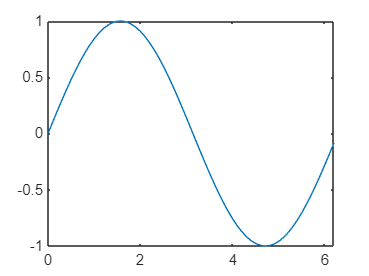

figure;
plot(x, y)

% Un plot è... un oggetto
help plot

 plot - 2-D line plot
    This MATLAB function creates a 2-D line plot of the data in Y versus the
    corresponding values in X.

    Vector and Matrix Data
      plot(X,Y)
      plot(X,Y,LineSpec)
      plot(X1,Y1,...,Xn,Yn)
      plot(X1,Y1,LineSpec1,...,Xn,Yn,LineSpecn)
      plot(Y)
      plot(Y,LineSpec)

    Table Data
      plot(tbl,xvar,yvar)
      plot(tbl,yvar)

    Additional Options
      plot(ax,___)
      plot(___,Name,Value)
      p = plot(___)

    Input Arguments
      X - x-coordinates
        scalar | vector | matrix
      Y

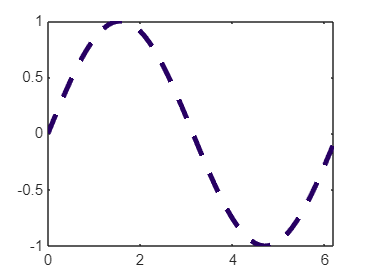

% Guarda tutti quei parametri. Guardali
plot(x,y, 'LineWidth',3, 'Color','#270063', 'LineStyle','--')

% Alcuni si possono anche abbreviare
plot(x,y, 'b--')
% Altro
xlabel('x')
ylabel('sin(x)')
legend('sin(x)')
grid("on") % o anche: grid on

hold on % le aggiunte restano sulla stessa figura
z = cos(x)

z =     1.0000    0.9950    0.9801    0.9553    0.9211    0.8776    0.8253    0.7648    0.6967    0.6216    0.5403    0.4536    0.3624    0.2675    0.1700    0.0707   -0.0292   -0.1288   -0.2272   -0.3233   -0.4161   -0.5048   -0.5885   -0.6663   -0.7374   -0.8011   -0.8569   -0.9041   -0.9422   -0.9710   -0.9900   -0.9991   -0.9983   -0.9875   -0.9668   -0.9365   -0.8968   -0.8481   -0.7910   -0.7259   -0.6536   -0.5748   -0.4903   -0.4008   -0.3073   -0.2108   -0.1122   -0.0124    0.0875    0.1865


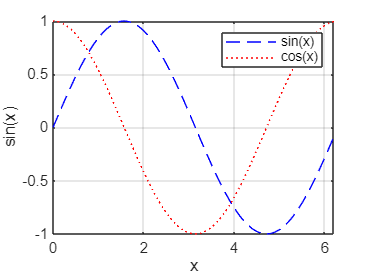

plot(x,z, 'r:')
legend('sin(x)', 'cos(x)')